% Test second order wave equation

close all, clear all

err1 = []; %Absolute error for the different mesh-sizes
err2 = []; %Relativ error for the different mesh-sizes

for l=1:4
k=2^(-l-3);    % timestep
h=k;  % space discretization step
H(l) = h; %saving h just for plot
n = 1/h;  % number of intervals per coordinate direction

T = 1;    % time interval [0,T]
gamma = 1/2;
c = 1 ;


nd = n+1; % number of node points in each direction
N = nd^2; % matrix size
xc = 0:h:1;
yc = 0:h:1;

nk = ceil(T/k); % number of timesteps

% create the space discretization matrix A-discrete negative Laplacian
e = ones(N,1);
A0 = spdiags([e,e,-4*e,e,e],[-nd,-1,0,1,nd],N,N);
for j = 1:nd-1
    A0(j*nd,j*nd+1) = 0;
    A0(j*nd+1,j*nd) = 0;    
end

## Space discretization

[xg,yg]=meshgrid(xc,yc);
x = reshape(xg,N,1);
y = reshape(yg,N,1);
% Find the boundary points
bnd1=find(x==0);
bnd2=find(y==0);
bnd3=find(x==1);
bnd4=find(y==1);
bnda=union(bnd1,bnd2,'stable');
bndb=union(bnd3,bnd4,'stable');
bndr=union(bnda,bndb,'stable');

g = 1:N;
nbndr = setdiff(g,bndr);

## Exact solution and rhs.

 4:th order polynomial in time and 2:nd order in space so the solution should only have an error in time and exact solution in space.

% frhs = @(x,y,t,c) 12*t.^2.*(x.^2-x).*(y.^2-y) - c^2*(2.*(y.^2-y).*(t.^4+1) + 2.*(x.^2-x).*(t.^4+1));
% uex = @(x,y,t) (x.^2-x).*(y.^2-y).*(t.^4+1)+pi;
% udex = @(x,y,t) (x.^2-x).*(y.^2-y).*4.*t.^3;

frhs = @(x,y,t) +30.*t.^4.*(- x.^2 + x).*(- y.^2 + y) + (8.*(- y.^2 + y).*(t.^6 + 1))./25 + (8.*(- x.^2 + x).*(t.^6 + 1))./25;
uex = @(x,y,t) (x.^2-x).*(y.^2-y).*(t.^6+1);
udex = @(x,y,t) 6.*t.^5.*(- x.^2 + x).*(- y.^2 + y);

1:st order polynomial in time and 4:th order in space so the solution should only have an error in space and exact solution in time.

% frhs = @(x,y,t) -c^2*(12.*x.^2.*(y.^4-y).*(t+1) + 12.*y.^2.*(x.^4-x).*(t+1));
% uex = @(x,y,t) (x.^4-x).*(y.^4-y).*(t+1);
% udex = @(x,y,t) (x.^4-x).*(y.^4-y);

Initial condition that gives eigenfunction solution.

% frhs = @(x,y,t,c) x*0; %source term
% uex = @(x,y,t) sin(pi*x).*sin(pi*y).*cos(c*pi*t*sqrt(2));
% udex = @(x,y,t) -c*pi*sqrt(2).*sin(pi*x).*sin(pi*y).*sin(c*pi*t*sqrt(2));

Other eigen solution, phase shifted.

% frhs = @(x,y,t,c) x*0;
% uex = @(x,y,t) sin(pi*x).*sin(pi*y).*sin(c*pi*t*sqrt(2));
% udex = @(x,y,t) c*pi*sqrt(2).*sin(pi*x).*sin(pi*y).*cos(c*pi*t*sqrt(2));

Antother polynomial solution

% frhs = inline('x.*y.*(1-x).*(1-y)+2*c^2*(y.*(1-y)+x.*(1-x)).*(1+t.^2/2)','x','y','t','c');
% uex  = inline('x.*y.*(1-x).*(1-y).*(1+t.^2/2)','x','y','t');
% udex = inline('x.*y.*(1-x).*(1-y).*t','x','y','t');  % first derivative 



%figure(1),clf
%plot3(x,y,u0,'o')  % plot the initial condition


## Initializing

To start the metrod we need one step with a different method Rewrite as a system of equations and apply Euler Backwards (I-(k/h)^2A0)u(k) = kw(0)+u(0)+kf(x,y,k), w(0) is the second initial condition

I2 = speye(N,N);
w0 = udex(x,y,0);   % derivative at t=0
u0 = uex(x,y,0);    % solution   at t=0
rho = (c*k/h)^2;
compute_first_step_trapets  % compute u1

err_abs = zeros(nk,1);
err_rel = zeros(nk,1);
err_abs(1,1) = norm(uex1-u1);
err_rel(1,1) = norm(uex1-u1)/norm(uex1);
cnt = 1;

## Solution in time

u2 = zeros(N,1); % just allocation
A = I2 - gamma*rho*A0;
err_tot = 0;
restart = 1;
maxit = n;
tol=1e-6;
for tcur = k:k:T-k
    uex_cur2 = uex(x,y,tcur+k);
    uex_cur1 = uex(x,y,tcur);
    uex_cur0 = uex(x,y,tcur-k);
    b = rho*A0*u1 + k^2*(gamma*frhs(x,y,tcur+k,c) + (1 - 2*gamma)*frhs(x,y,tcur,c) + gamma*frhs(x,y,tcur-k,c));
    [Acur,bcur]=Dirichlet(A,b,[uex_cur0, uex_cur1, uex_cur2],bndr);
    xi = Acur\bcur;
    %[xi_it,fl,relres,iter,resvec] = agmg(Acur,bcur,restart,tol,maxit,1);
    %figure(7),clf,plot(xi-xi_it)
    %figure(8),clf,semilogy(resvec,'o-'),xlabel(['Dof: ' int2str(N) ', iterations: ' int2str(iter)])

    u1(bndr) = 0; % to get the boundary rigth
    u0(bndr) = 0;
    u2 = xi + 2*u1 - u0;  % solution at t_cur+k
    u0 = u1;
    u1 = u2;
    cnt = cnt + 1;
    err_abs(cnt,1) = norm(uex_cur2-u2);
    err_rel(cnt,1) = norm(uex_cur2-u2)/norm(uex_cur2);
end
err1 = [err1 err_abs(end)/nd];

err1 = 0.0331

err1 =     0.0331    0.0089


err1 =     0.0331    0.0089    0.0023


err1 =     0.0331    0.0089    0.0023    0.0006


err2 = [err2 err_rel(end)];

err2 = 0.2644

err2 =     0.2644    0.0692


err2 =     0.2644    0.0692    0.0176


err2 =     0.2644    0.0692    0.0176    0.0044


end

Just creating the table


Tab = table;
factor = [0];
rate = [0];
for i = 1:length(err1)-1
    factor(i+1) = err1(i)/err1(i+1);
    rate(i+1) = log(err1(i)/err1(i+1))/log(H(i)/H(i+1));
end
Tab.DOF = (1./H'+1).^2;
Tab.timestepandmesh = H';
Tab.Error_abs = round(err1',3,'significant');
%Tab.Error_rel = err2';
Tab.Factor = round(factor',3,'significant');
Tab.Rate = round(rate',3,'significant');
Tab

Tab = 4×5 table
     DOF     timestepandmesh    Error_abs    Factor    Rate
    _____    _______________    _________    ______    ____

      289          0.0625         0.0331         0        0
     1089         0.03125        0.00893      3.71     1.89
     4225        0.015625         0.0023      3.88     1.96
    16641       0.0078125       0.000584      3.95     1.98


Table with factor between consecutieve entries.

Just a convergance plot

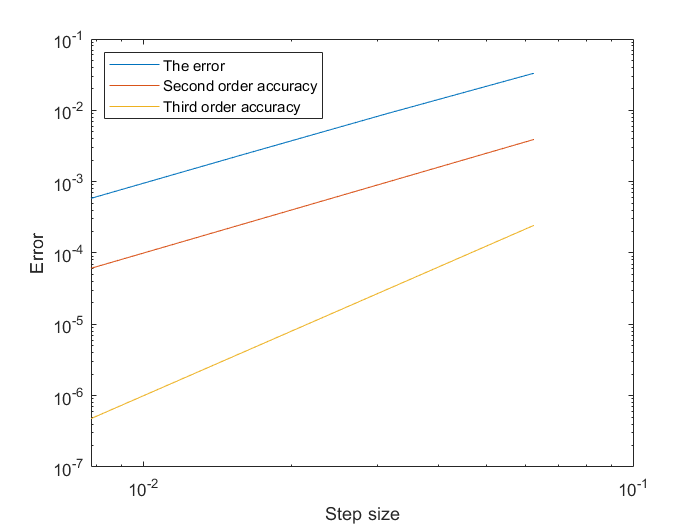

clf
loglog(H,err1)
hold on
loglog(H,H.^2)
hold on
loglog(H,H.^3)
%title 'L_2 norm of the error'
xlabel 'Step size'
ylabel 'Error'
legend('The error', 'Second order accuracy', 'Third order accuracy', 'location','NW')